load('../shortChordEEG/data.mat')
addpath('./src/Classification')

addpath('./src/Conf2Dist')

addpath('./src/Visualization')



getname = @(x) inputname(1);

% LDA NO PCA


%get good samples
Z1 = trRows2cube(corrX1, 39);
Z1good = Z1(:,[16 17 18 19 20 21], :);
Z1good2D = cube2trRows(Z1good);

Z2 = trRows2cube(corrX2, 39);
Z2good = Z2(:,[16 17 18 19 20 21], :);
Z2good2D = cube2trRows(Z2good);

%get bad samples
Z1bad = Z1(:,[1 2 3 4 5 6], :);
Z1bad2D = cube2trRows(Z1bad);

Z2bad = Z2(:,[1 2 3 4 5 6], :);
Z2bad2D = cube2trRows(Z2bad);



%LDA NO PCA
[CM, accuracy, pVal, classifierInfo] = classifyEEG([corrX1;corrX2], ...
    [Y1exemplar; Y2exemplar], 'classify', 'LDA', 'shuffleData', 1);


DMLDA = computeDistanceMatrix(CM, 'symmetrize', 'geometric') ;

Computing distance matrix...
Normalize: diagonal
Symmetrize: geometric
Distance: linear
Rank distance: none



plotDendrogram(DMLDA, 'distMethod', 'ward', 'nodeLabels', {'cT' 'cD' 'cF' 'cS' 'bT' ...
    'bD' 'bF' 'bS' 'fT' 'fD' 'fF' 'fS'}, 'nodeColors', ['b' 'm' 'g' ...
    'r' 'b' 'm' 'g' 'r' 'b' 'm' 'g' 'r']);

CASE: COLOR NODE


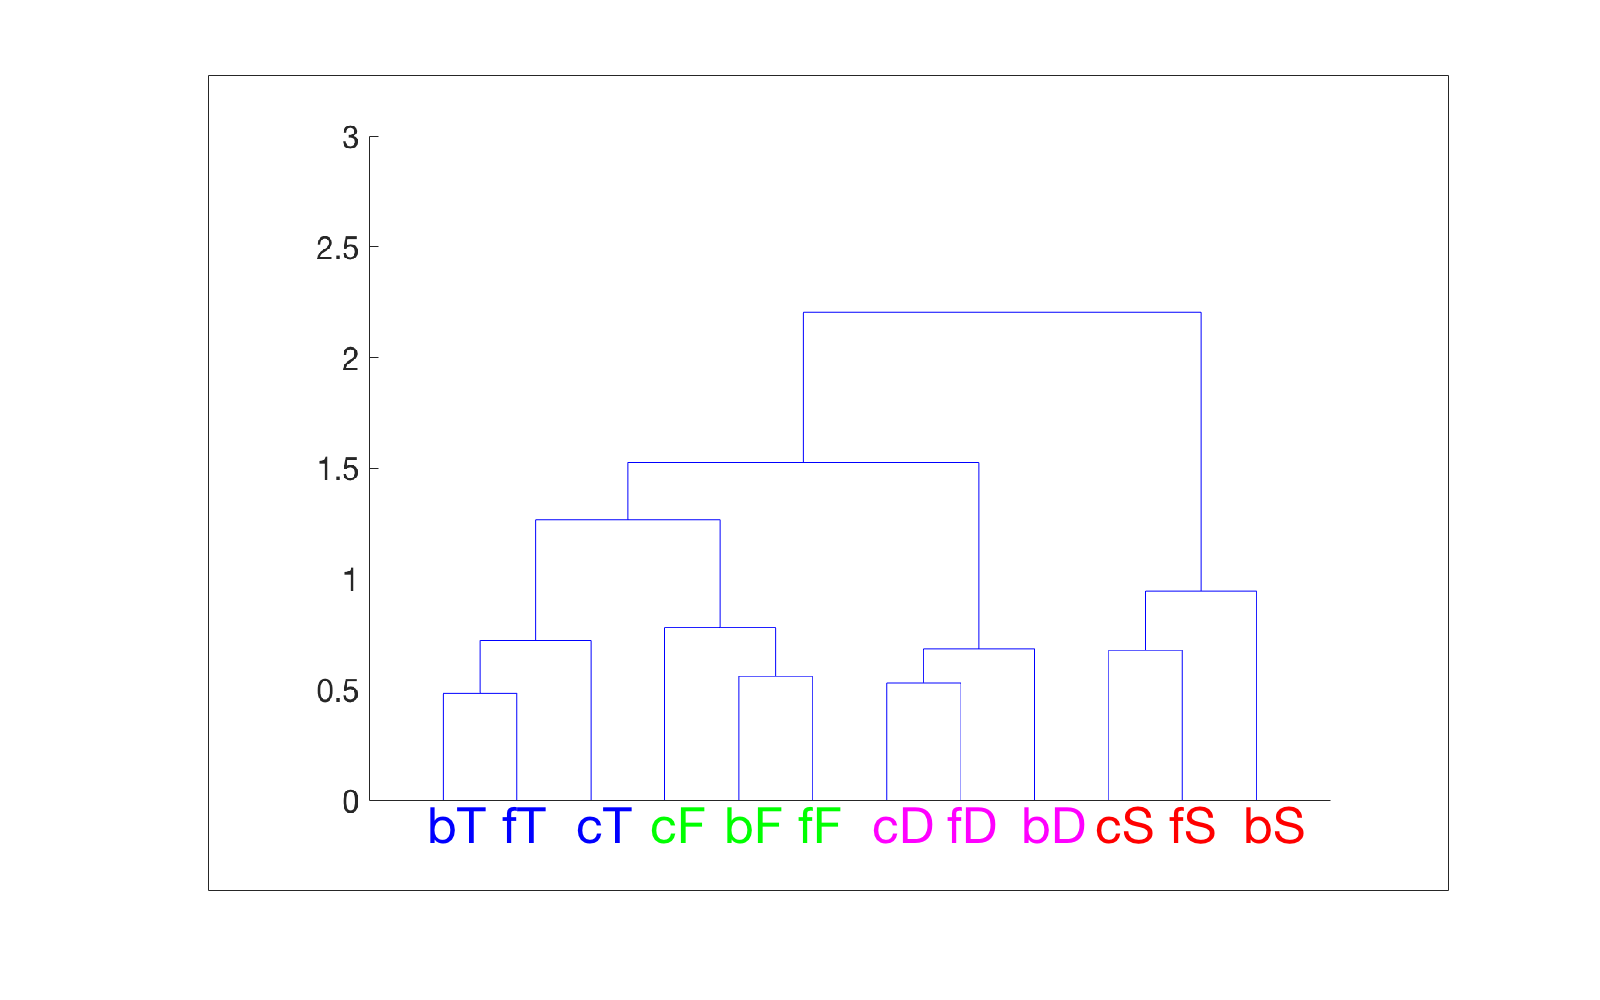


img = getframe(gcf);

img.Color = 'yellow';
imwrite(img.cdata, ['DMLDA' '.jpg']);

[CM, accuracy, pVal, classifierInfo] = classifyEEG([Z1good2D;Z2good2D], ...
    [Y1exemplar; Y2exemplar], 'classify', 'LDA', 'shuffleData', 1);


DMLDAgood = computeDistanceMatrix(CM, 'symmetrize', 'geometric') ;

Computing distance matrix...
Normalize: diagonal
Symmetrize: geometric
Distance: linear
Rank distance: none



plotDendrogram(DMLDAgood, 'distMethod', 'ward', 'nodeLabels', {'cT' 'cD' 'cF' 'cS' 'bT' ...
    'bD' 'bF' 'bS' 'fT' 'fD' 'fF' 'fS'}, 'nodeColors', ['b' 'm' 'g' ...
    'r' 'b' 'm' 'g' 'r' 'b' 'm' 'g' 'r']);

CASE: COLOR NODE


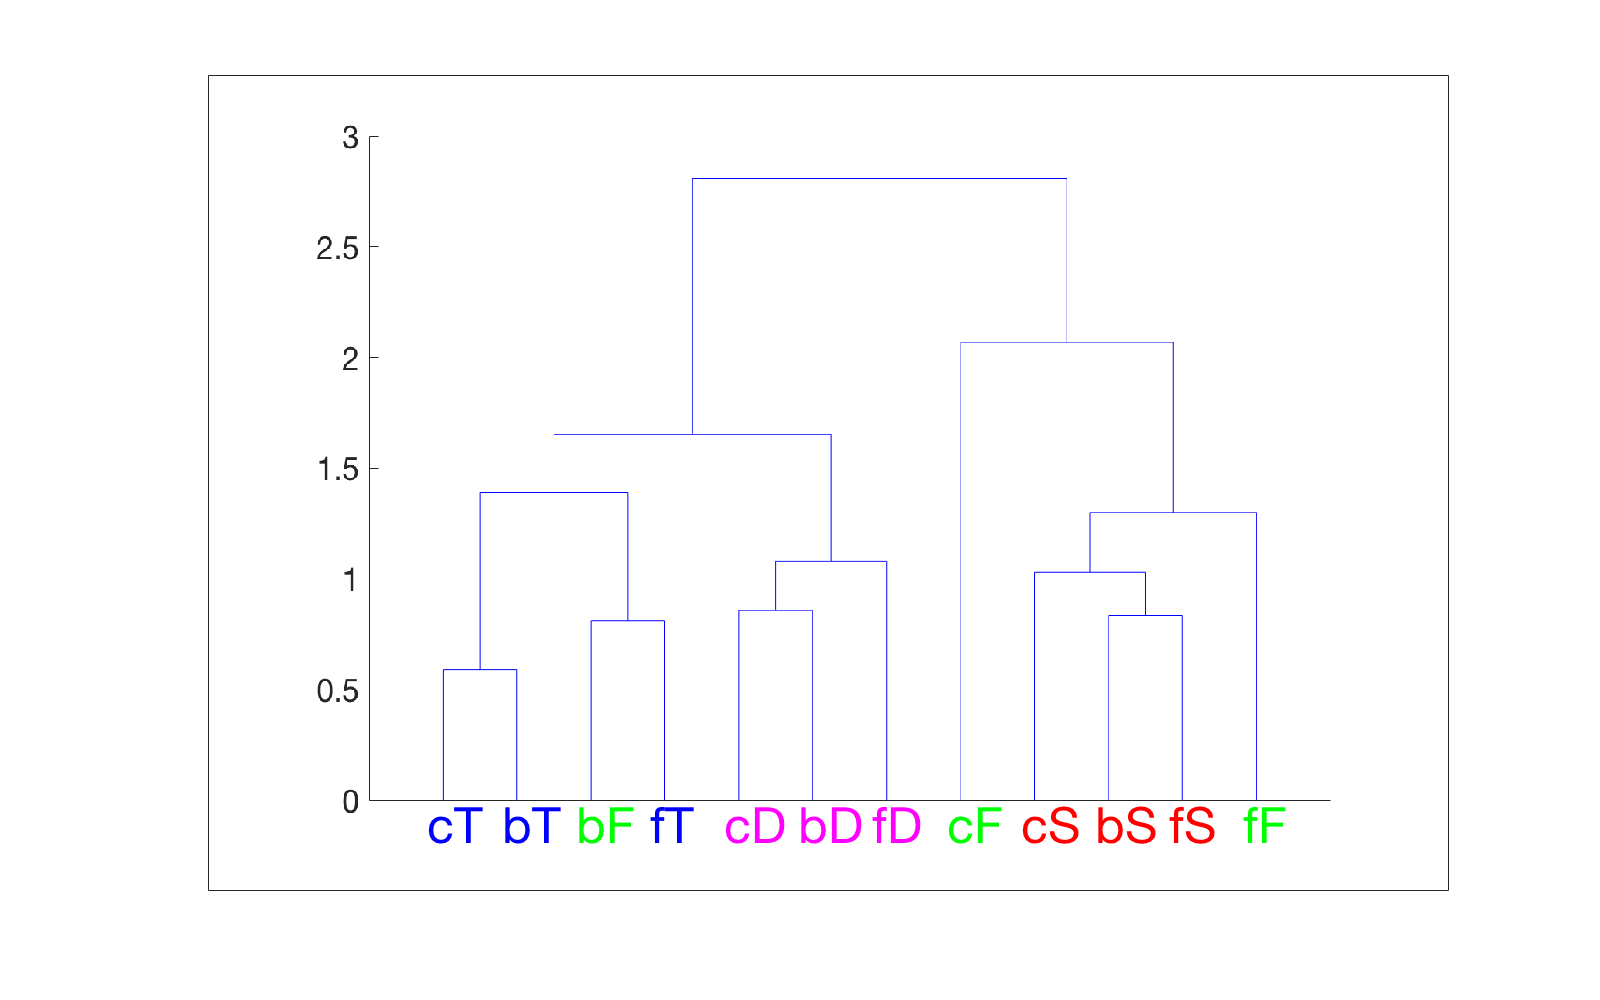


img = getframe(gcf);

img.Color = 'yellow';
imwrite(img.cdata, ['DMLDAgood' '.jpg']);


[CM, accuracy, pVal, classifierInfo] = classifyEEG([Z1bad2D;Z2bad2D], ...
    [Y1exemplar; Y2exemplar], 'classify', 'LDA', 'shuffleData', 1);


DMLDAbad = computeDistanceMatrix(CM, 'symmetrize', 'geometric') ;

Computing distance matrix...
Normalize: diagonal
Symmetrize: geometric
Distance: linear
Rank distance: none



plotDendrogram(DMLDAbad, 'distMethod', 'ward', 'nodeLabels', {'cT' 'cD' 'cF' 'cS' 'bT' ...
    'bD' 'bF' 'bS' 'fT' 'fD' 'fF' 'fS'}, 'nodeColors', ['b' 'm' 'g' ...
    'r' 'b' 'm' 'g' 'r' 'b' 'm' 'g' 'r']);

CASE: COLOR NODE


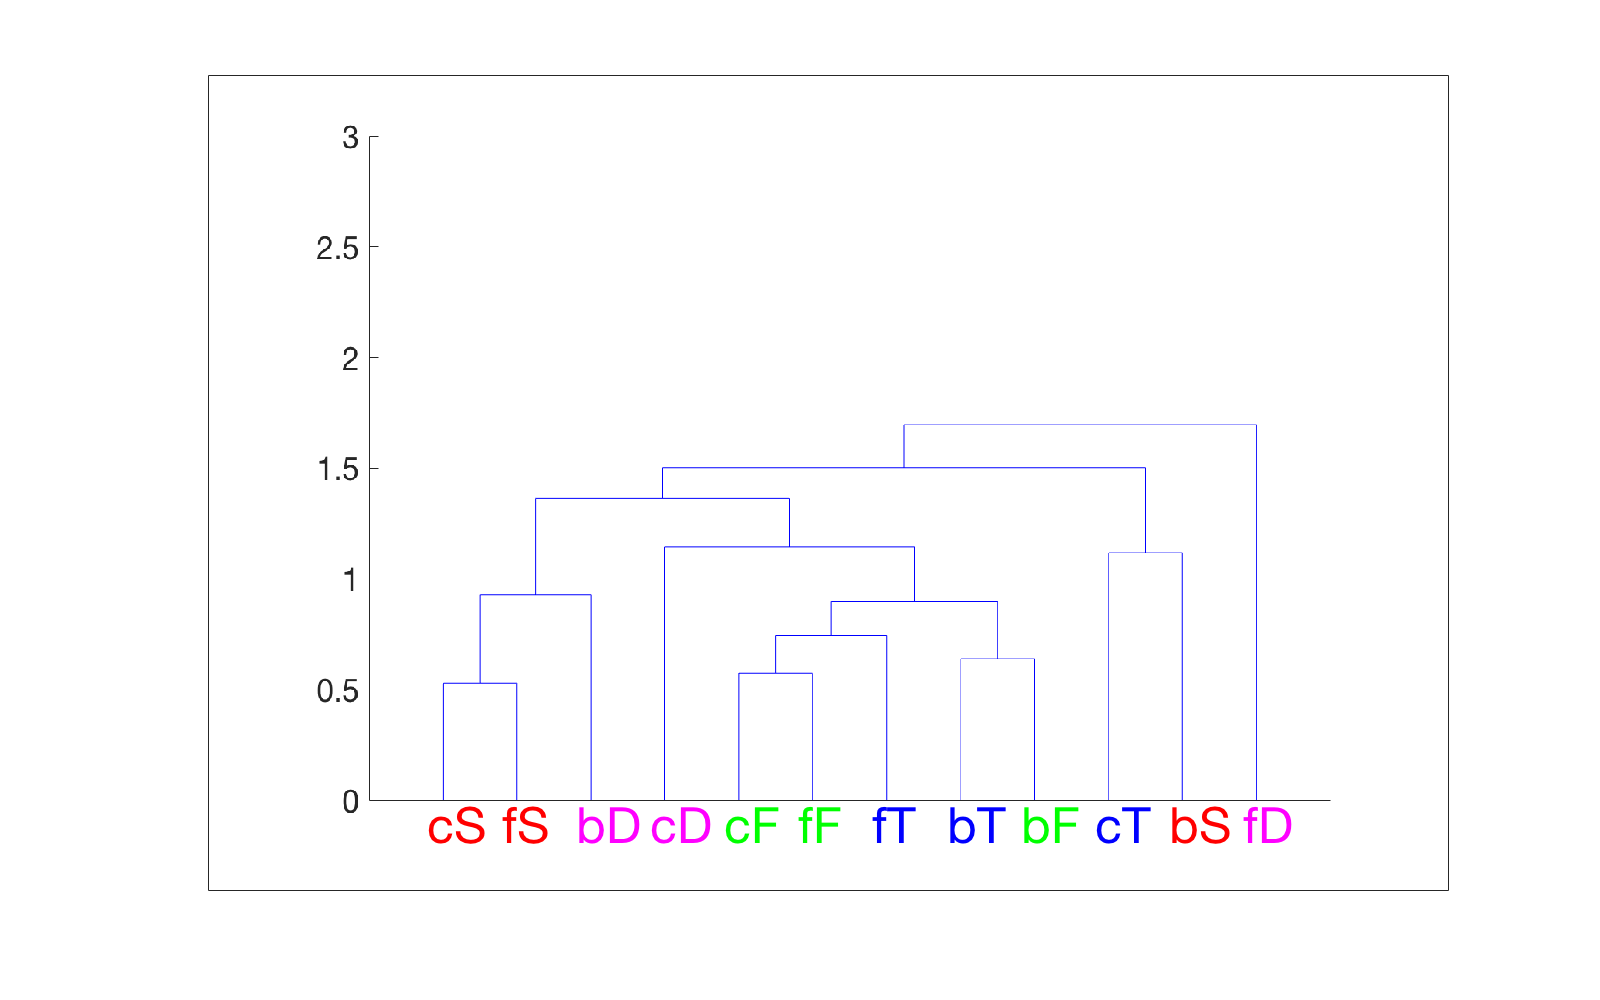


img = getframe(gcf);

img.Color = 'yellow';
imwrite(img.cdata, ['DMLDAbad' '.jpg']);


% LDA PCA
[CMg, accuracyg, pVal, classifierInfo] = classifyEEG([corrX1;corrX2], ...
    [Y1exemplar; Y2exemplar], 'classify', 'LDA', 'PCA', .9, ...
    'PCAinFold', 1, 'shuffleData', 1)

getting PCs
got 224 PCs
getting PCs
got 220 PCs
getting PCs
got 221 PCs
getting PCs
got 220 PCs
getting PCs
got 223 PCs
getting PCs
got 222 PCs
getting PCs
got 220 PCs
getting PCs
got 219 PCs
getting PCs
got 221 PCs
getting PCs
got 225 PCs


CMg =     28    12     9    13    31    11    14    21    34    13    17    13
    15    31    14    19    17    20    15    12    10    19    24    20
    10    23    24    22    13    24    18    10    21    19    20    12
    17    16    13    47     2     9    10    26    14    12    14    36
    37    10    15     3    44     7    22    13    34    10    12     9
    19    33    17    12    12    24    20    16     7    26    18    12
    15    19    13    16    23    13    40    12    22    18    16     9
    15     9    18    28    14    19    10    24    23    11    13    32
    30     8    14    18    28     7    24    22    34     9    10    12
    10    24    19    15    15    25    16    16    10    30    22    14


accuracyg = 0.1451

pVal = NaN

classifierInfo = struct with fields:
          Normalize: ''
        shuffleData: 'on'
      averageTrials: ''
    permutationTest: ''
                PCA: ''
          PCAinFold: ''
             nFolds: ''
         classifier: ''



DMLDAPCA = computeDistanceMatrix(CM, 'symmetrize', 'geometric') 

Computing distance matrix...
Normalize: diagonal
Symmetrize: geometric
Distance: linear
Rank distance: none


DMLDAPCA =          0    0.2276    0.2167    0.4001    0.3970    0.2005    0.0219   -0.2649    0.3216   -0.3387    0.3021    0.2248
    0.2276         0    0.1453   -0.2479   -0.0607   -0.5612    0.1762    0.1633    0.0501   -0.2247    0.2887    0.0770
    0.2167    0.1453         0    0.1522   -0.1374    0.0625   -0.0787    0.2472   -0.0607   -0.4361   -0.1180    0.2578
    0.4001   -0.2479    0.1522         0    0.3577    0.1461    0.3545    0.2362    0.0800    0.0241    0.1317    0.1438
    0.3970   -0.0607   -0.1374    0.3577         0    0.1073   -0.0351    0.1359   -0.0338    0.1655   -0.0735    0.4406
    0.2005   -0.5612    0.0625    0.1461    0.1073         0    0.0742    0.0253   -0.1524    0.1708   -0.1650    0.1353
    0.0219    0.1762   -0.0787    0.3545   -0.0351    0.0742         0   -0.0809    0.0726   -0.0754    0.2234    0.4002
   -0.2649    0.1633    0.2472    0.2362    0.1359    0.0253   -0.0809         0   -0.4142   -0.8619    0.0144   -0.0435
    0.3216    0.0501 


plotDendrogram(DMLDAPCA  , 'distMethod', 'ward', 'nodeLabels', {'cT' 'cD' 'cF' 'cS' 'bT' ...
    'bD' 'bF' 'bS' 'fT' 'fD' 'fF' 'fS'}, 'nodeColors', ['b' 'm' 'g' ...
    'r' 'b' 'm' 'g' 'r' 'b' 'm' 'g' 'r']);

CASE: COLOR NODE



img = getframe(gcf);

img.Color = 'yellow';
imwrite(img.cdata, ['DMLDAPCA' '.jpg']);

[CMg, accuracyg, pVal, classifierInfo] = classifyEEG([Z1good2D;Z2good2D], ...
    [Y1exemplar; Y2exemplar], 'classify', 'LDA', 'PCA', .9, ...
    'PCAinFold', 1, 'shuffleData', 1)

getting PCs
got 54 PCs
getting PCs
got 54 PCs
getting PCs
got 54 PCs
getting PCs
got 54 PCs
getting PCs
got 54 PCs
getting PCs
got 53 PCs
getting PCs
got 53 PCs
getting PCs
got 55 PCs
getting PCs
got 53 PCs
getting PCs
got 54 PCs


CMg =     33    21    12     9    25    15    16    11    42    12     8    12
    18    30    11    16    20    10    11    14    22    31    13    20
    17    16    14    18    15    17    11    20    18    28    17    25
    11    17    18    33     7    12    18    22    13    17    18    30
    39    15    16    10    32    14    17     8    26    16    10    13
    20    17    13    23    11    15    17    16    19    31    13    21
    21     9    13    16    18    10    24    36    23    17     9    20
    19    12    15    33    10     8    12    24    21    15    10    37
    31    13     8    14    31    10    12    17    47    22     4     7
    18    21    10    12     8    31     8    14    19    50    12    13


accuracyg = 0.1350

pVal = NaN

classifierInfo = struct with fields:
          Normalize: ''
        shuffleData: 'on'
      averageTrials: ''
    permutationTest: ''
                PCA: ''
          PCAinFold: ''
             nFolds: ''
         classifier: ''



DMLDAPCAgood = computeDistanceMatrix(CM, 'symmetrize', 'geometric') 

Computing distance matrix...
Normalize: diagonal
Symmetrize: geometric
Distance: linear
Rank distance: none


DMLDAPCAgood =          0    0.2276    0.2167    0.4001    0.3970    0.2005    0.0219   -0.2649    0.3216   -0.3387    0.3021    0.2248
    0.2276         0    0.1453   -0.2479   -0.0607   -0.5612    0.1762    0.1633    0.0501   -0.2247    0.2887    0.0770
    0.2167    0.1453         0    0.1522   -0.1374    0.0625   -0.0787    0.2472   -0.0607   -0.4361   -0.1180    0.2578
    0.4001   -0.2479    0.1522         0    0.3577    0.1461    0.3545    0.2362    0.0800    0.0241    0.1317    0.1438
    0.3970   -0.0607   -0.1374    0.3577         0    0.1073   -0.0351    0.1359   -0.0338    0.1655   -0.0735    0.4406
    0.2005   -0.5612    0.0625    0.1461    0.1073         0    0.0742    0.0253   -0.1524    0.1708   -0.1650    0.1353
    0.0219    0.1762   -0.0787    0.3545   -0.0351    0.0742         0   -0.0809    0.0726   -0.0754    0.2234    0.4002
   -0.2649    0.1633    0.2472    0.2362    0.1359    0.0253   -0.0809         0   -0.4142   -0.8619    0.0144   -0.0435
    0.3216    0.0


plotDendrogram(DMLDAPCAgood  , 'distMethod', 'ward', 'nodeLabels', {'cT' 'cD' 'cF' 'cS' 'bT' ...
    'bD' 'bF' 'bS' 'fT' 'fD' 'fF' 'fS'}, 'nodeColors', ['b' 'm' 'g' ...
    'r' 'b' 'm' 'g' 'r' 'b' 'm' 'g' 'r']);

CASE: COLOR NODE



img = getframe(gcf);

img.Color = 'yellow';
imwrite(img.cdata, ['DMLDAPCAgood ' '.jpg']);

[CM, accuracy, pVal, classifierInfo] = classifyEEG([Z1bad2D;Z2bad2D], ...
    [Y1exemplar; Y2exemplar], 'classify', 'LDA', 'PCA', .9, ...
    'PCAinFold', 1, 'shuffleData', 1)

getting PCs
got 55 PCs
getting PCs
got 56 PCs
getting PCs
got 55 PCs
getting PCs
got 56 PCs
getting PCs
got 55 PCs
getting PCs
got 55 PCs
getting PCs
got 55 PCs
getting PCs
got 58 PCs
getting PCs
got 55 PCs
getting PCs
got 55 PCs


CM =     11    24    11    18    24    18    16    18    23    11    21    21
     9    19    18    28    26    13    19    13    20    15    17    19
    10    16    20    19    24    15    10    23    19    20    20    20
    21    27    17    20     9    25    10    12    14    21    19    21
     8    17    19     9    22    23    23    16    20    21    19    19
    23    17    17    17    25    18    18    16    18    15    13    19
    14    24    13    15    26    10    18    10    19    25     8    34
    19    18    15    18    21    15    15    18    24    15    20    18
    14    20    22    11    24    14    25    18    24    11    14    19
    18    24    24    21    18    13    22    18    19    16    12    11


accuracy = 0.0849

pVal = NaN

classifierInfo = struct with fields:
          Normalize: ''
        shuffleData: 'on'
      averageTrials: ''
    permutationTest: ''
                PCA: ''
          PCAinFold: ''
             nFolds: ''
         classifier: ''



DMLDAPCAbad = computeDistanceMatrix(CM, 'symmetrize', 'geometric') 

Computing distance matrix...
Normalize: diagonal
Symmetrize: geometric
Distance: linear
Rank distance: none


DMLDAPCAbad =          0   -0.0166    0.2929   -0.3108    0.1093   -0.4460   -0.0636   -0.3143   -0.1044   -0.0607   -0.5754    0.0230
   -0.0166         0    0.1294   -0.4105   -0.0283    0.1961   -0.1547    0.1728    0.0634   -0.0882   -0.2691    0.0211
    0.2929    0.1294         0    0.1014   -0.0180    0.1584    0.3991    0.0211    0.0668   -0.2247   -0.3038    0.1584
   -0.3108   -0.4105    0.1014         0    0.5709   -0.0865    0.3545    0.2254    0.4336   -0.1739   -0.6310    0.0189
    0.1093   -0.0283   -0.0180    0.5709         0   -0.2050   -0.2289    0.0789    0.0465   -0.0363   -0.0180    0.0327
   -0.4460    0.1961    0.1584   -0.0865   -0.2050         0    0.2546    0.1393    0.2362    0.1771    0.0691    0.2153
   -0.0636   -0.1547    0.3991    0.3545   -0.2289    0.2546         0    0.3196   -0.0486   -0.3819    0.1308    0.1128
   -0.3143    0.1728    0.0211    0.2254    0.0789    0.1393    0.3196         0         0    0.0318   -0.5635    0.2362
   -0.1044    0.06


plotDendrogram(DMLDAPCAbad, 'distMethod', 'ward', 'nodeLabels', {'cT' 'cD' 'cF' 'cS' 'bT' ...
    'bD' 'bF' 'bS' 'fT' 'fD' 'fF' 'fS'}, 'nodeColors', ['b' 'm' 'g' ...
    'r' 'b' 'm' 'g' 'r' 'b' 'm' 'g' 'r']);

CASE: COLOR NODE


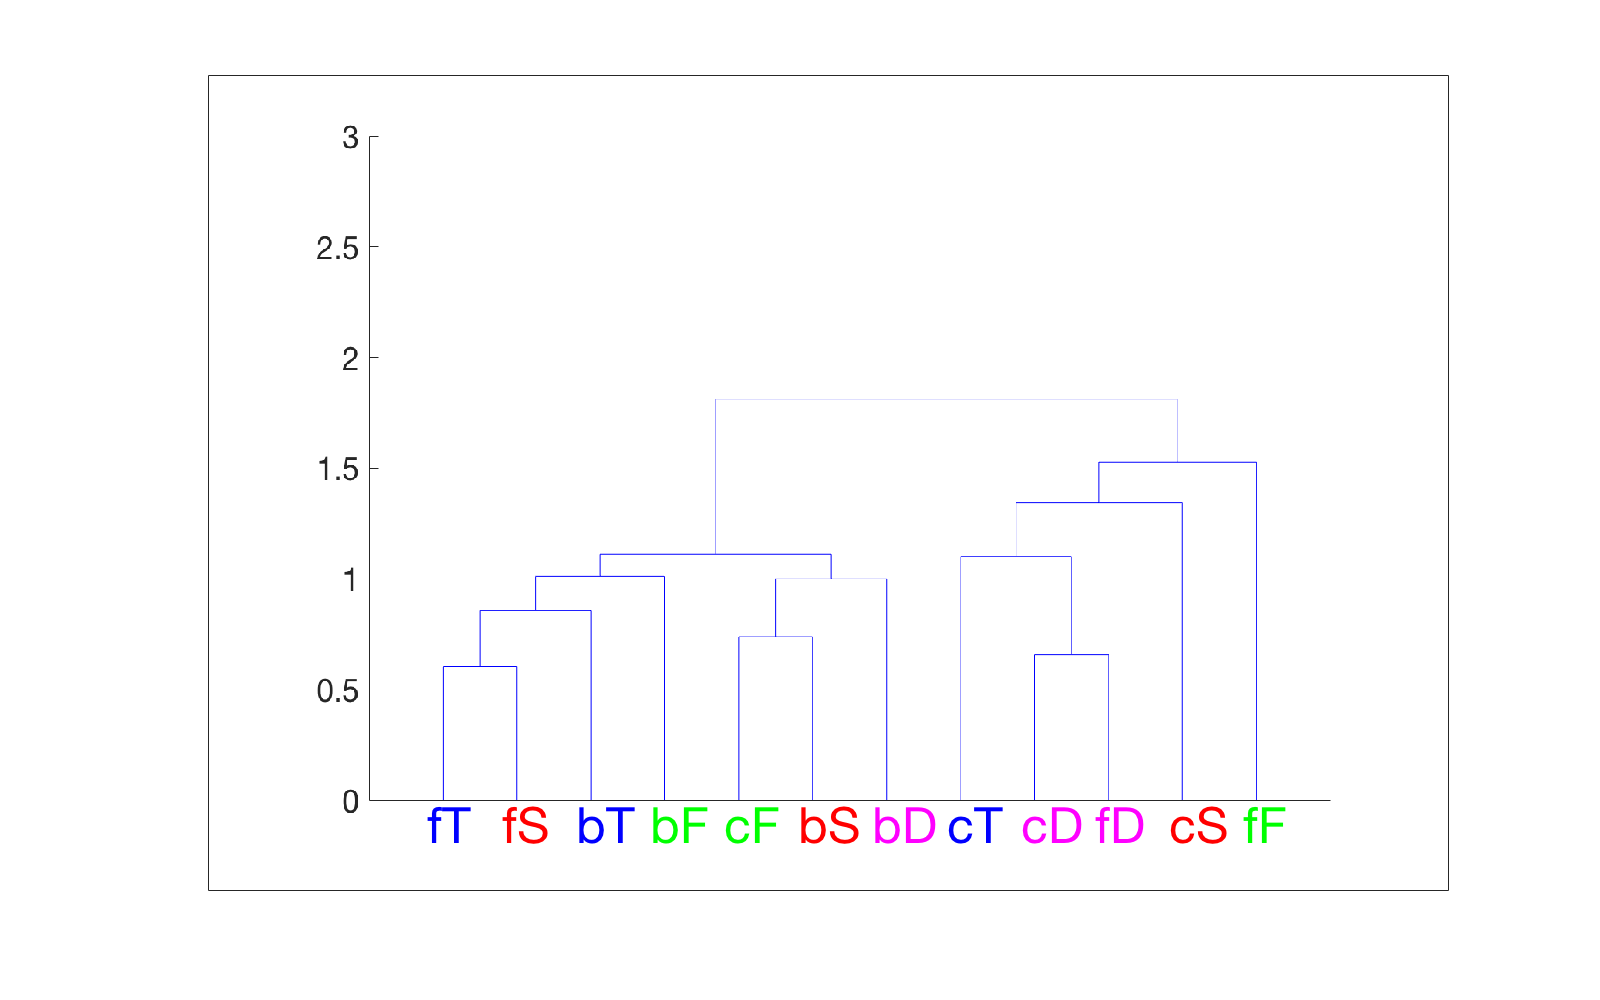


img = getframe(gcf);

img.Color = 'yellow';
imwrite(img.cdata, ['DMLDAPCAbad' '.jpg']);

% SVM NO PCA
[CM, accuracy, pVal, classifierInfo] = classifyEEG([corrX1;corrX2], ...
    [Y1exemplar; Y2exemplar], 'classify', 'SVM','shuffleData', 1);

.....*..*
optimization finished, #iter = 3138
nu = 0.038333
obj = -7.532588, rho = -0.137205
nSV = 257, nBSV = 0
.......*...*
optimization finished, #iter = 4081
nu = 0.049205
obj = -9.497039, rho = -0.245086
nSV = 287, nBSV = 0
.....*...*
optimization finished, #iter = 3121
nu = 0.040659
obj = -7.887980, rho = -0.353259
nSV = 269, nBSV = 0
........*....*
optimization finished, #iter = 4697
nu = 0.067122
obj = -13.123311, rho = 0.095321
nSV = 313, nBSV = 0
......*...*
optimization finished, #iter = 3809
nu = 0.047515
obj = -9.171207, rho = -0.295091
nSV = 287, nBSV = 0
.......*....*
optimization finished, #iter = 4334
nu = 0.047363
obj = -9.212583, rho = -0.377443
nSV = 293, nBSV = 0
.........*.....*
optimization finished, #iter = 5445
nu = 0.071061
obj = -13.679575, rho = 0.086646
nSV = 323, nBSV = 0
.......*...*
optimization finished, #iter = 4053
nu = 0.052710
obj = -10.252742, rho = -0.140864
nSV = 295, nBSV = 0
.....*..*
optimization finished, #iter = 2834
nu = 0.033311
obj = -6.5


DMSVM = computeDistanceMatrix(CM, 'symmetrize', 'geometric') ;

Computing distance matrix...
Normalize: diagonal
Symmetrize: geometric
Distance: linear
Rank distance: none



save('DMSVM.mat', 'DMSVM')

plotDendrogram(DMSVM, 'distMethod', 'ward', 'nodeLabels', {'cT' 'cD' 'cF' 'cS' 'bT' ...
    'bD' 'bF' 'bS' 'fT' 'fD' 'fF' 'fS'}, 'nodeColors', ['b' 'm' 'g' ...
    'r' 'b' 'm' 'g' 'r' 'b' 'm' 'g' 'r']);

CASE: COLOR NODE



img = getframe(gcf);
img.Color = 'yellow';
imwrite(img.cdata, ['DMSVM' '.jpg']);




[CM, accuracy, pVal, classifierInfo] = classifyEEG([Z1good2D;Z2good2D], ...
    [Y1exemplar; Y2exemplar], 'classify', 'SVM', 'shuffleData', 1)

DMSVMgood = computeDistanceMatrix(CM, 'symmetrize', 'geometric') 

plotDendrogram(DMSVMgood, 'distMethod', 'ward', 'nodeLabels', {'cT' 'cD' 'cF' 'cS' 'bT' ...
    'bD' 'bF' 'bS' 'fT' 'fD' 'fF' 'fS'}, 'nodeColors', ['b' 'm' 'g' ...
    'r' 'b' 'm' 'g' 'r' 'b' 'm' 'g' 'r']);

img = getframe(gcf);
img.Color = 'yellow';
imwrite(img.cdata, ['DMSVMgood' '.jpg']);


[CM, accuracy, pVal, classifierInfo] = classifyEEG([Z1bad2D;Z2bad2D], ...
    [Y1exemplar; Y2exemplar], 'classify', 'SVM', 'shuffleData', 1)

DMSVMbad = computeDistanceMatrix(CM, 'symmetrize', 'geometric') 

plotDendrogram(DMSVMbad, 'distMethod', 'ward', 'nodeLabels', {'cT' 'cD' 'cF' 'cS' 'bT' ...
    'bD' 'bF' 'bS' 'fT' 'fD' 'fF' 'fS'}, 'nodeColors', ['b' 'm' 'g' ...
    'r' 'b' 'm' 'g' 'r' 'b' 'm' 'g' 'r']);

img = getframe(gcf);
img.Color = 'yellow';
imwrite(img.cdata, ['DMSVMbad' '.jpg']);



% SVM PCA
[CM, accuracy, pVal, classifierInfo] = classifyEEG([corrX1;corrX2], ...
    [Y1exemplar; Y2exemplar], 'classify', 'SVM', 'PCA', .9, ...
    'PCAinFold', 1, 'shuffleData', 1)

DMSVMPCA = computeDistanceMatrix(CM, 'symmetrize', 'geometric') 

plotDendrogram(DMSVMPCA, 'distMethod', 'ward', 'nodeLabels', {'cT' 'cD' 'cF' 'cS' 'bT' ...
    'bD' 'bF' 'bS' 'fT' 'fD' 'fF' 'fS'}, 'nodeColors', ['b' 'm' 'g' ...
    'r' 'b' 'm' 'g' 'r' 'b' 'm' 'g' 'r']);

img = getframe(gcf);
img.Color = 'yellow';
imwrite(img.cdata, ['DMSVMPCA' '.jpg']);

[CM, accuracy, pVal, classifierInfo] = classifyEEG([Z1good2D;Z2good2D], ...
    [Y1exemplar; Y2exemplar], 'classify', 'SVM', 'PCA', .9, ...
    'PCAinFold', 1, 'shuffleData', 1)

DMSVMPCAgood = computeDistanceMatrix(CM, 'symmetrize', 'geometric') 

plotDendrogram(DMSVMPCAgood, 'distMethod', 'ward', 'nodeLabels', {'cT' 'cD' 'cF' 'cS' 'bT' ...
    'bD' 'bF' 'bS' 'fT' 'fD' 'fF' 'fS'}, 'nodeColors', ['b' 'm' 'g' ...
    'r' 'b' 'm' 'g' 'r' 'b' 'm' 'g' 'r']);

img = getframe(gcf);
img.Color = 'yellow';
imwrite(img.cdata, ['DMSVMPCAgood' '.jpg'])

[CM, accuracy, pVal, classifierInfo] = classifyEEG([Z1bad2D;Z2bad2D], ...
    [Y1exemplar; Y2exemplar], 'classify', 'SVM', 'PCA', .9, ...
    'PCAinFold', 1, 'shuffleData', 1)

DMSVMPCAbad = computeDistanceMatrix(CM, 'symmetrize', 'geometric')

plotDendrogram(DMSVMPCAbad, 'distMethod', 'ward', 'nodeLabels', {'cT' 'cD' 'cF' 'cS' 'bT' ...
    'bD' 'bF' 'bS' 'fT' 'fD' 'fF' 'fS'}, 'nodeColors', ['b' 'm' 'g' ...
    'r' 'b' 'm' 'g' 'r' 'b' 'm' 'g' 'r']);

img = getframe(gcf);
img.Color = 'yellow';
imwrite(img.cdata, ['DMSVMPCAbad' '.jpg'])